# Característiques locals

## Histograms of Oriented Gradients

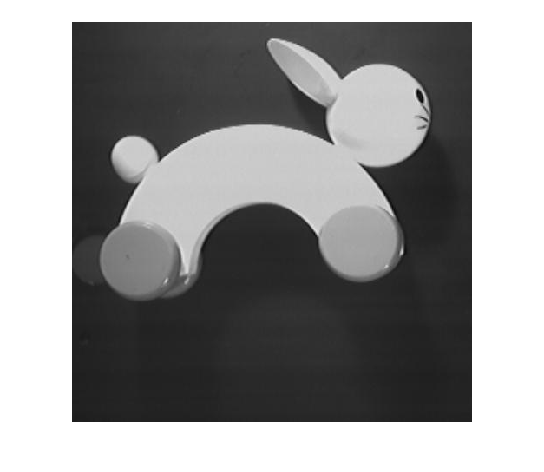

im = imread("rabbit.jpg");
imshow(im);

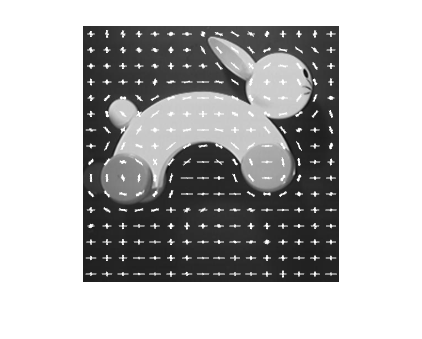

% normalitzar mida imatge
im = imresize(im, [256,256]);
% càlcul hog
[HoG, HoGdisplay] = extractHOGFeatures(im, 'CellSize', [16, 16], 'BlockSize', [3, 3], 'NumBins', 9);
imshow(im);
hold on
plot(HoGdisplay);
hold off

### Buscar un retall (cell)

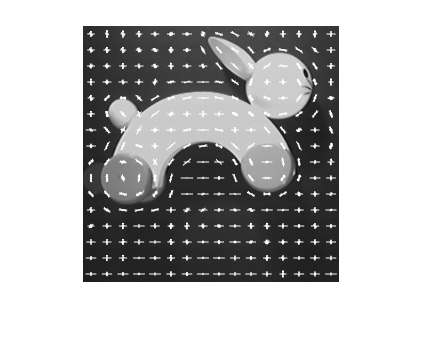

[c, f] = getpts;

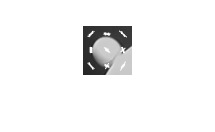

C = imcrop(im,[c - 24, f - 24, 48, 48]); % quadrat de 3x3 cells
figure
imshow(C);
hold on
[HoGC, HoGdisplayC] = extractHOGFeatures(C, 'CellSize', [16, 16], 'BlockSize', [3, 3], 'NumBins', 9);
plot(HoGdisplayC);
hold off

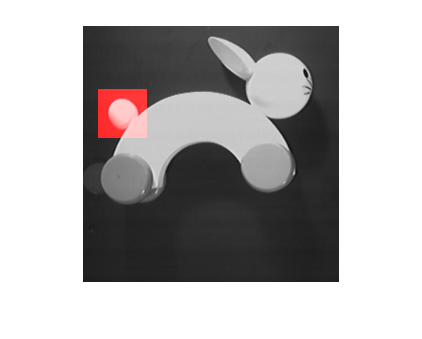


EF = reshape(HoG,[81,14*14])'; % 14 blocs x 14 blocs = (16 cells - 3 mida bloc + 1) | 81 features = 9 bins x 3 x 3 mida bloc

Semblanca = zeros([14*14, 1]); % 14 blocs x 14 blocs
for i = 1:14*14
    Semblanca(i) = sum(min(EF(i,:), HoGC));
end

[val, block_pos] = max(Semblanca);

% Dibuixar-ho a sobre
block_x = uint8(block_pos/14);
block_y = mod(block_pos,14);
pos_x = 16*block_x + 24;
pos_y = 16*block_y + 8;

im_rgb(:,:,1) = im;
im_rgb(:,:,2) = im;
im_rgb(:,:,3) = im;
im_rgb(max(1,pos_y-24):min(255,pos_y+24),max(1,pos_x-24):min(255,pos_x+24),1) = 255;
figure, imshow(im_rgb);

## Histogrames de colors

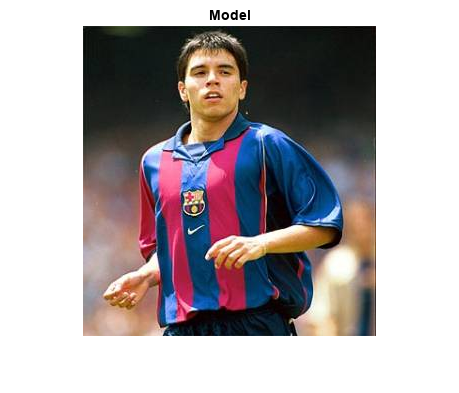

im = imread("team1.jpg");
figure, imshow(im), title('Model');

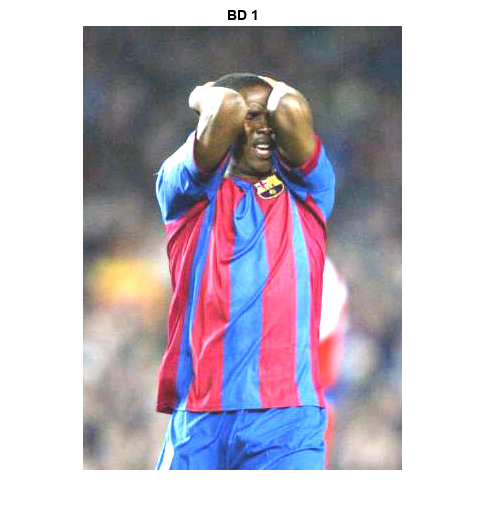

im1 = imread("team2.jpg");
im2 = imread("team5.jpg");
im3 = imread("team11.jpg");
im4 = imread("team12.jpg");
im5 = imread("team8.jpg");
figure, imshow(im1), title('BD 1');

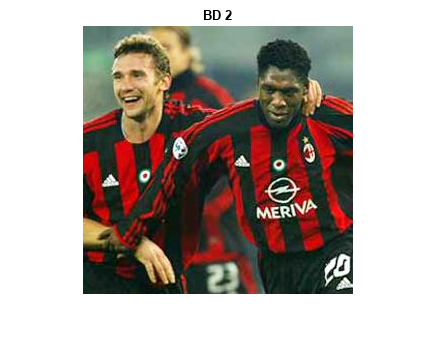

figure, imshow(im2), title('BD 2');

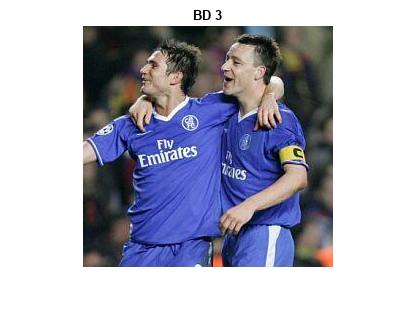

figure, imshow(im3), title('BD 3');

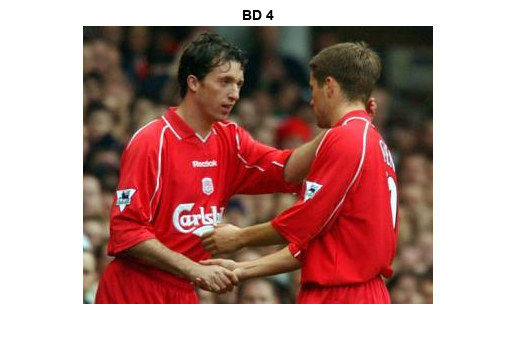

figure, imshow(im4), title('BD 4');

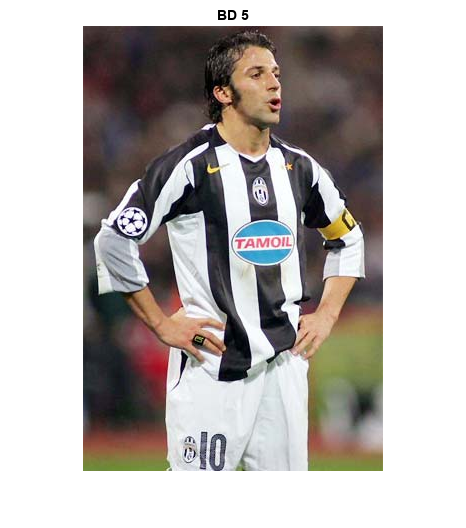

figure, imshow(im5), title('BD 5');

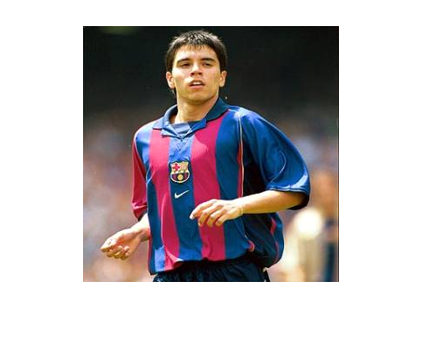


% Normalitzar mida imatges
im = imresize(im, [256,256]);
im1 = imresize(im1, [256,256]);
im2 = imresize(im2, [256,256]);
im3 = imresize(im3, [256,256]);
im4 = imresize(im4, [256,256]);
im5 = imresize(im5, [256,256]);

% calcular histograma normalitzat amb components (r, g)
hist = calculateHistogram(im);

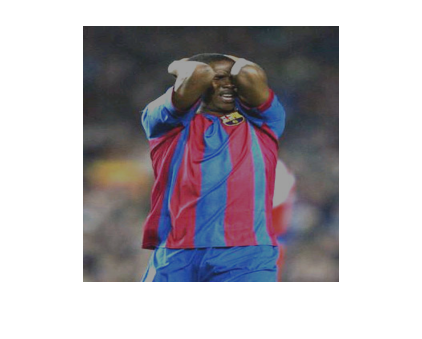

hist1 = calculateHistogram(im1);

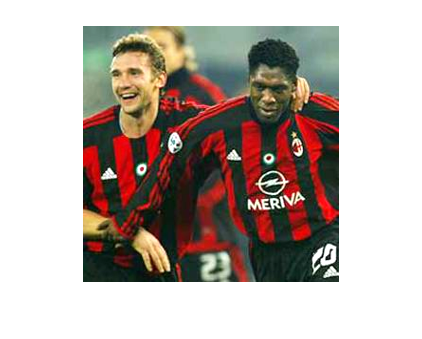

hist2 = calculateHistogram(im2);

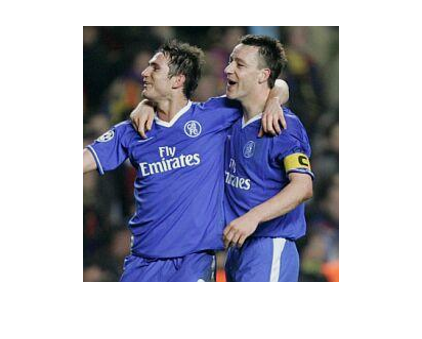

hist3 = calculateHistogram(im3);

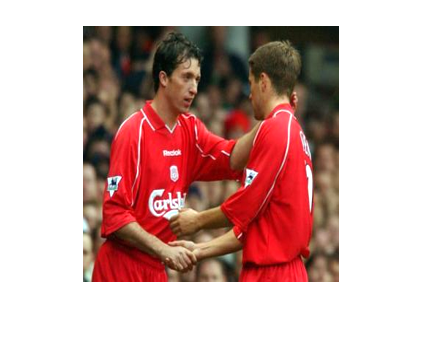

hist4 = calculateHistogram(im4);

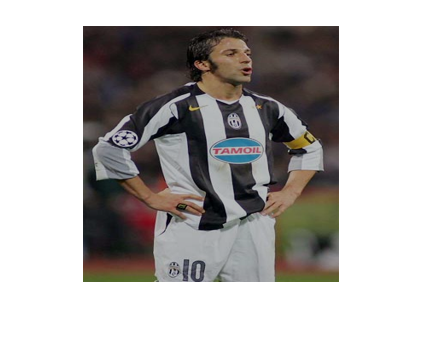

hist5 = calculateHistogram(im5);

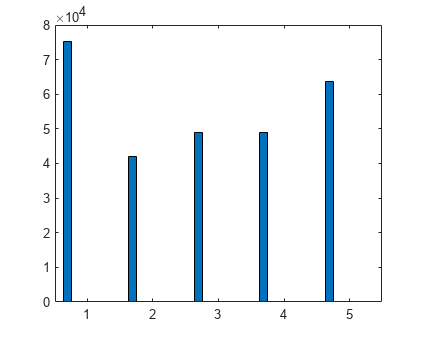


% trobar histograma semblant
s = zeros(5);
s(1) = compareHistograms(hist, hist1);
s(2) = compareHistograms(hist, hist2);
s(3) = compareHistograms(hist, hist3);
s(4) = compareHistograms(hist, hist4);
s(5) = compareHistograms(hist, hist5);
bar(s);

function [hist] = calculateHistogram(im)
I = sum(rgb2gray(im),'all')/(size(im,1)*size(im,2))/255;
im_norm = (double(im)/255)/(3*I);
imshow(im_norm);
hist = zeros([16,16]);
for i = 1:size(im, 1)
    for j = 1:size(im, 2)
        r = min(floor(15*im_norm(i,j,1)) + 1, 16);
        g = min(floor(15*im_norm(i,j,2)) + 1, 16);
        hist(r,g) = hist(r,g) + 1;
    end
end
end
%%
function [s] = compareHistograms(hist1, hist2)
s = 0;
for i = 1:16
    for j = 1:16
        if (hist1(i,j) + hist2(i,j) > 0)
            s = s + (hist1(i,j) - hist2(i,j))*(hist1(i,j) - hist2(i,j))/(hist1(i,j) + hist2(i,j));
        end
    end
end
end